# Lasso Regression

See Fama and French, 1993, "Common Risk Factors in the Returns on Stocks and Bonds," *Journal of Financial Economics*

**The Fama/French factors are constructed using the 6 value-weight portfolios formed on size and book-to-market.**

***[Factor #1: ****Market****] ****ri = rf + Beta*(rm - rf)*

SMB (Small Minus Big) is the average return on the three small portfolios minus the average return on the three big portfolios,

***[Factor #2: ****Size****] SMB**** = 1/3 (Small Value + Small Neutral + Small Growth) - 1/3 (Big Value + Big Neutral + Big Growth). *

HML (High Minus Low) is the average return on the two value portfolios minus the average return on the two growth portfolios,

***[Factor #3: ****Value vs. Growth****] HML**** =1/2 (Small Value + Big Value) - 1/2 (Small Growth + Big Growth).*

Rm-Rf, the excess return on the market, value-weight return of all CRSP firms incorporated in the US and listed on the NYSE, AMEX, or NASDAQ that have a CRSP share code of 10 or 11 at the beginning of month t, good shares and price data at the beginning of t, and good return data for t minus the one-month Treasury bill rate (from Ibbotson Associates).

***[Factor #4:**** Momentum****]*** ***UMD = ****Up-Minus-Down = Top 50% of highest performing stocks in the last 12 months - Bottom 50% of lowest performing stocks in the last 12 months*

***Data reference:***

- [https://mba.tuck.dartmouth.edu/pages/faculty/ken.french/data_library.html](https://mba.tuck.dartmouth.edu/pages/faculty/ken.french/data_library.html)

- [https://finance.yahoo.com/quote](https://finance.yahoo.com/quote)

**Columbia University - Machine Learning for Enterprise Risk Management**                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                 [malphons@mathworks.com](http://malphons@mathworks.com) **|** [https://www.linkedin.com/in/marshallalphonso](https://www.linkedin.com/in/marshallalphonso)

### Load in Equity Data

load FF4Data.mat
holdoutPCT = 0.2;
retSecurity = E.smallReturns.ABG;
[T,Ttrain,Ttest] = getCrossValFactorData(retSecurity,FF4,holdoutPCT);
idxRand = randi([1 width(E.smallReturns)],10,1);
Tbig = [T array2table(E.smallReturns{:,idxRand})];

### Lasso Model


$$y=\beta_1 *\textrm{Fi}\;$$


[b,FitInfo] = lasso(Tbig{:,2:end},Tbig.rSec_Minus_rRiskFree,'CV',10);
idxLambdaMinMSE = FitInfo.IndexMinMSE;
bMSE = b(:,idxLambdaMinMSE);
yLasso   = Tbig{:,2:end}*bMSE(:,end);

MdlActual = fitlm(Tbig,'rSec_Minus_rRiskFree ~ rMkt_Minus_rRiskFree + rSizeFactor + rValueGrowthFactor + rMomentum')

MdlActual = Linear regression model:
    rSec_Minus_rRiskFree ~ 1 + rMkt_Minus_rRiskFree + rSizeFactor + rValueGrowthFactor + rMomentum

Estimated Coefficients:
                            Estimate        SE          tStat        pValue  
                            _________    _________    _________    __________

    (Intercept)             0.0075803    0.0050198       1.5101       0.13213
    rMkt_Minus_rRiskFree       1.7354      0.14931       11.623    8.0558e-26
    rSizeFactor                 1.971       0.4416       4.4634    1.1632e-05
    rValueGrowthFactor        0.36879      0.44268       0.8331       0.40549
    rMomentum               -0.052882      0.62478    -0.084641       0.93261


Number of observations: 290, Error degrees of freedom: 285
Root Mean 

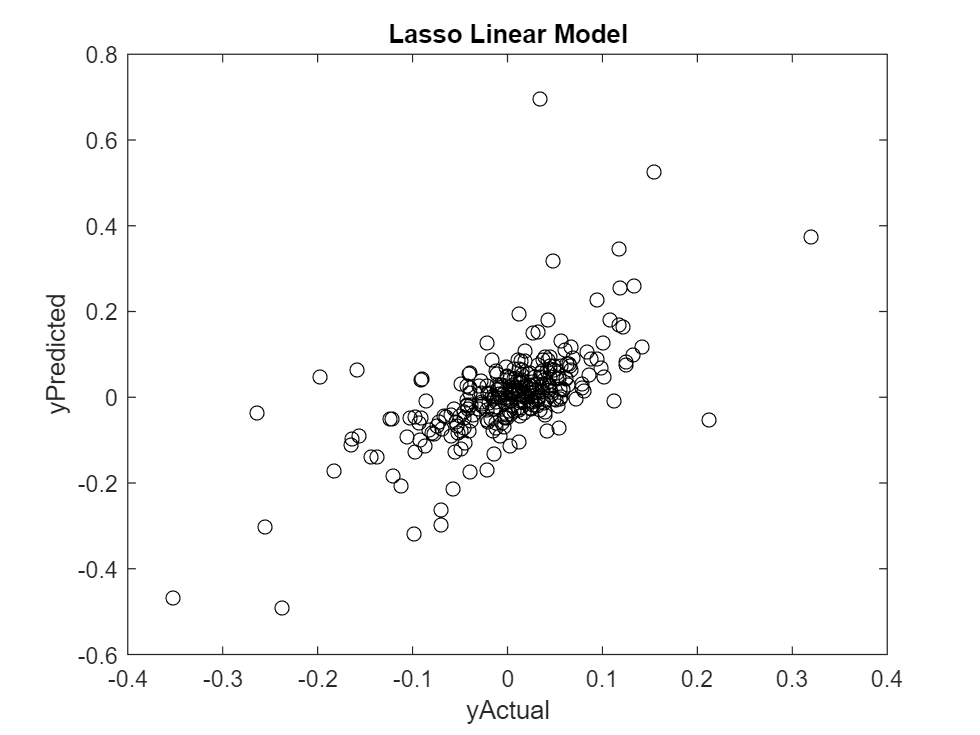

yFitActual = predict(MdlActual,Tbig);

figure
plot(yFitActual,yLasso,'ko')
title('Lasso Linear Model')
xlabel('yActual')
ylabel('yPredicted')